# Assignment 1: Steady Convection-Diffusion transport

## Introduction

Consider the one-dimensional convection-diffusion equation with Dirichlet boundary conditions on both ends:

  
$$\begin{cases}\displaystyle a\frac{du}{dx}-\nu \frac{d^2u}{dx^2}=s & \textrm{in} \ [0,1] \\
& \\
u(0)=u_D^{(0)} & \\
& \\
u(1)=u_D^{(1)}
\end{cases}$$


We can solve this problem through finite elements by calling the class 'SteadyConvectionDiffusionProblem'. However, we need to define some preliminar properties.

## Mesh set-up

We first define a 1D mesh composed of line elements. With the following lines we can define, for instance, a mesh consisting of 50 elements:

nEl           = 50;
xnode         = 0:1/nEl:1;
s.coord       = xnode';
s.connec(:,1) = 1:length(xnode)-1;
s.connec(:,2) = 2:length(xnode);
m             = Mesh.create(s)

m =   LineMesh with properties:

        geometryType: 'Line'
                type: 'LINE'
               kFace: 0
               coord: [51×1 double]
              connec: [50×2 double]
                ndim: 1
               nelem: 50
              nnodes: 51
           nnodeElem: 2
           coordElem: [1×2×50 double]
       interpolation: [1×1 Line_Linear]
               edges: []
               faces: []
       boundaryNodes: []
    boundaryElements: []


## Defining the Lagrangian function

Thus, we shall define the kind of interpolation that our finite element function will employ. Now, we will define a P1 FE function (linear interpolation) with empty coefficients.

fieldDim = 1;
uTrial   = LagrangianFunction.create(m,fieldDim,'P1');

## Dirichlet boundary conditions

We also need to define the left and right Dirichlet values, $u_D^{\left(0\right)}$ and $u_D^{\left(1\right)}$ respectively. For example:

dir.left  = 0;
dir.right = 1;

## Source definition

Lastly, we can define analytically the source function as:

source = @(x) 10*exp(-5*x(1,:,:))-4*exp(-x(1,:,:));

## Solving the problem

Hence, we solve the whole problem by gathering all defined properties and calling the main class. Imagine that we would like to employ the original Galerkin formulation. Then, we create:

s.mesh      = m;
s.trial     = uTrial;
s.sHandle   = source;
s.dirValues = dir;
s.stab      = 'Galerkin';
prob        = SteadyConvectionDiffusionProblem(s);

The solution can finally be obtained explicitly in function of the parameters $a$ and $\nu$.

a  = 1;
nu = 0.1;
prob.compute(a,nu);
u = prob.trial.copy();

Besides, we can plot the solution:

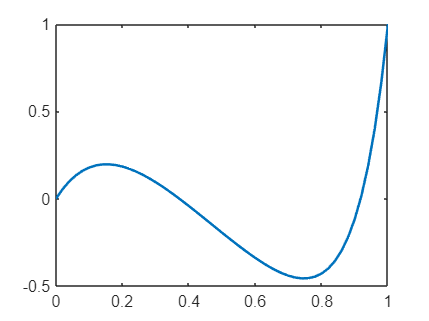

prob.plot();

Finally, we also can compute the residual at each node:

dudx      = Grad(u).project('P1',m);
d2udx2    = Grad(dudx).project('P1',m);
sP1       = AnalyticalFunction.create(source,1,m).project('P1');
resValues = a*dudx.fValues - nu*d2udx2.fValues - sP1.fValues;

## Questions

**1. The variable **$u$ **has a public property called fValues. Briefly describe which is the mathematical meaning of this property and its implication regarding the fundamentals of finite element methods.**

Write here your answer.

**2. Take a look to the 'resValues' variable (the PDE residual at each node). Explain why all values are not nearly equal to zero.**

Write here your answer

**3. Rewrite in the end of this script ('auxiliar function definition' section) all the code together as a function of the inputs provided. Note that the Peclet number must be used as an input.**

**4. Run previous function using the same data as in the introduction section and plot the solution. Then, run again changing the Peclet number to Pe=3.33 and add the new solution to the plot. What can you observe?**

**5. Run the same function using 100 elements, the upwind scheme, Pe=5 and the boundary conditions:**


$$u_D^{\left(0\right)} =u_D^{\left(1\right)} =0$$



$$s\left(x\right)=1$$


**Then, compare and analyze the new numerical result with the Galerkin solution and the following exact solution:**


$$u(x)=\displaystyle\frac{1}{a}\left(x+\frac{1-\exp{\displaystyle\frac{xa}{\nu}}}{\exp{\displaystyle\frac{a}{\nu}}-1}\right)$$


Write here your answer

**6. Note that when trying to use the SUPG scheme, the code fails because it is incompleted. Debug the code and solve the issue. Hence, run again the function with the same data as question 4 with SUPG, and add the solution to previous plot. Add below the new plot along with comments, and a screenshot of the location inside the code where you have solved the SUPG issue.**

Write here your answer

**7. Run the function using just 10 elements, Pe=5 and the boundary conditions:**


$$\begin{array}{l}
u_D^{\left(0\right)} =0\\
u_D^{\left(1\right)} =1
\end{array}$$



$$s\left(x\right)=\sin \left(\pi x\right)$$


**Then, compare and analyze the numerical results obtained with the upwind and SUPG schemes and the following exact solution:**


$$u(x)=c_1+c_2\exp{\displaystyle\frac{xa}{\nu}} + \displaystyle\frac{1}{c_0}(\nu\pi\sin(\pi x)-a\cdot\cos(\pi x))$$


**with **$c_0=\pi(a^2+\nu^2\pi^2)$**,** $c_1=(-c_0+a(\exp{(a/\nu)}+1))/(c_0(\exp{(a/\nu)}-1))$ **and** $c_2=(c_0-2a)/(c_0(\exp{(a/\nu)}-1))$.

Write here your answer

## **Auxiliar function definition**

function u = mainSteadyConvDif1D(nElem,dirLeft,dirRight,sHandle,stab,Pe)
a = 1;

% Write here your code...
end